In this document we will explore the concept of a "valid design" for a single variable-curvature segment. We will first implement the forward kinematics of a rod with linear curvature. Then, we will compute the externally induced forces and moments along it at each point, and plot these points in the reaction space. Finally, we will compute the internal reaction forces along an arm held at that shape, and also plot these points within the reaction space.

% Define arm base curve
% First we define the arm's design
rho_outer = 0.08;
rho_inner = 0.015;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
1, 1, 1, 1;
0, 0, 0, 0;
-rhos;
];

f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

l_0 = 0.5;

g_0 = Pose2.hat([0, 0, -pi/2]);
N_poses = 10;

% Combine the design parameters into a struct
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;

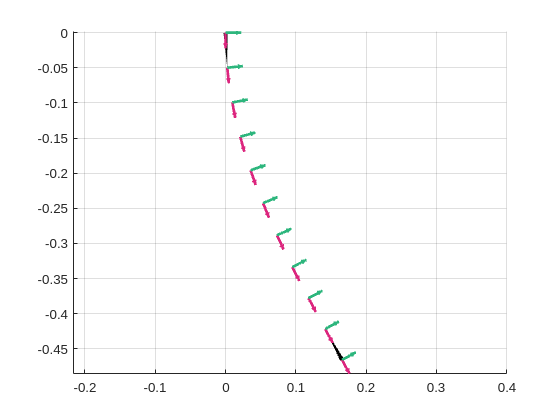

% Define the shape that the arm is held at
a = -1;
b = 1;

l = 0.5;
f_affine_curvature = @(s) [
    l*ones(size(s));
    zeros(size(s));
    a*s + b
];
s = linspace(0, 1, N_poses);
poses = f_calc_poses(g_0, f_affine_curvature, N_poses);
segment_twists = f_affine_curvature(s);

ax = axes(figure());
plot_poses(poses, ax);
grid on

Now let's apply a load to the tip of this rod and consider the reactions across it:

Q_tip = [0; -10; 0];
q = calc_external_wrench(segment_twists, Q_tip, g_0);
a_target = -q;

Now given the pressures of each muscle in the arm, compute the internal reaction force supplied along the length of the arm

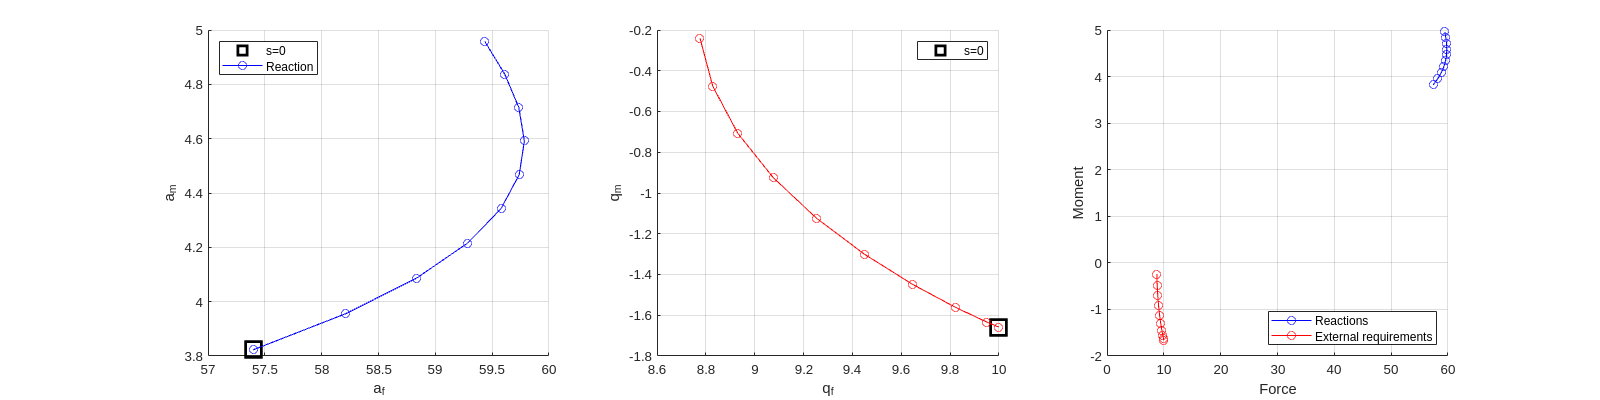

p = [15; 0; 15; 0]; %kPa
reaction_forces = calc_reaction_wrench(segment_twists, p, struct_design);

% Now we plot the two against each other
figure("position", [0, 0, 1600, 400])
subplot(1, 3, 1)
hold on
plot(reaction_forces(1, 1), reaction_forces(3, 1), "ksquare", "markersize", 15, "linewidth", 3)
plot(reaction_forces(1, :), reaction_forces(3, :), "b-o")
legend("s=0", "Reaction", location="Northwest")
xlabel("a_f")
ylabel("a_m")
grid on

subplot(1, 3, 2)
hold on
plot(q(1, 1), q(3, 1), "ksquare", "markersize", 15, "linewidth", 3);
plot(q(1, :), q(3, :), 'r-o');
xlabel("q_f")
ylabel("q_m")
legend("s=0")
grid on

subplot(1, 3, 3)
hold on
plot(reaction_forces(1, :), reaction_forces(3, :), "b-o");
plot(q(1, :), q(3, :), "r-o");
xlabel("Force")
ylabel("Moment")
legend("Reactions", "External requirements", location="southeast")
grid on

The crucial questions for extending our previous work to the variable curvature arm are:

- What will happen to this plot when we traverse the pressure contour? 

- How can we read "designability" from the variable curvature arm's pressure contour?

Now let's try doing this for a whole range of pressures along the pressure contour

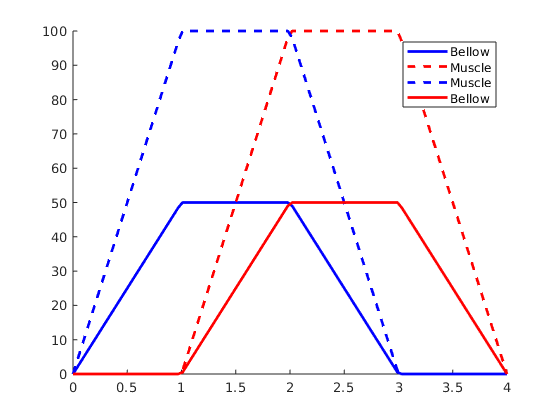

N_edge = 25;
t = linspace(0, 4, 4*N_edge);
p_max_bellow = 50;
p_max_muscle = 100;
p_max = [p_max_bellow, p_max_muscle, p_max_muscle, p_max_bellow];
ps = outline_pressure_space(p_max, [1, 2, 1, 2], N_edge);
figure()
hold on
plot(t, ps(1, :), "b-", "linewidth", 2);
plot(t, ps(2, :), "r--", "linewidth", 2);
plot(t, ps(3, :), "b--", "linewidth", 2);
plot(t, ps(4, :), 'r-', "linewidth", 2);
set(gcf, "visible", true)
legend("Bellow", "Muscle", "Muscle", "Bellow")

mat_3d_rxns = zeros([size(reaction_forces), length(t)]);
for i = 1 : size(ps, 2)
    mat_3d_rxns(:, :, i) = calc_reaction_wrench(segment_twists, ps(:, i), struct_design);
end

% For each element within the segment, track how the reactions moved as we
% traversed the pressure contour.
paths_qf = zeros(N_poses, length(t));
paths_qm = zeros(N_poses, length(t));
text_labels = cell(1, N_poses);
for i = 1 : N_poses
    paths_qf(i, :) = squeeze(mat_3d_rxns(1, i, :));
    paths_qm(i, :) = squeeze(mat_3d_rxns(3, i, :));
    text_labels{i} = sprintf("s=%.2f", s(i));
end

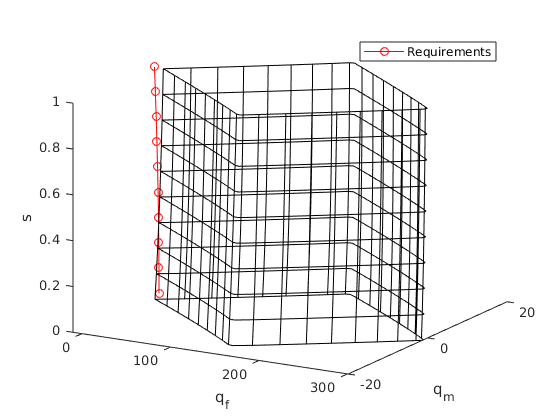

mat_s = repmat(s, [N_edge*4, 1]);

figure()
hold on
plot3(a_target(1, :), a_target(3, :), s, 'r-o')
plot3(paths_qf(:, 1:3:end)', paths_qm(:, 1:3:end)', s, 'k');
plot3(paths_qf', paths_qm', mat_s, 'k');

xlabel("q_f")
ylabel("q_m")
zlabel("s")
legend("Requirements")
view(30, 20)
set(gcf, "visible", true)

% Find the pressure that will minimize the force residuals for when the arm
% is held at this shape.
tic
f_cost_pressure = @(pres) sum(vecnorm(check_equilibrium(segment_twists, Q_tip, pres, struct_design), 1));
[soln_p_min_residual] = fminunc(f_cost_pressure, [0; 0; 0; 0]);


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


soln_a_min_residual = calc_reaction_wrench(segment_twists, soln_p_min_residual, struct_design);
toc

Elapsed time is 0.172510 seconds.


% Find the pressure such that a(s=0) = [q_f, q_m]
tic
soln_p_rxn_at_base = fmincon(@(p) cost_first_reaction_diff(segment_twists, p, struct_design, a_target), [0; 0; 0; 0], [], [], [], [], [0; 0; 0; 0], [50; 100; 100; 50]);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


soln_a_rxn_at_base = calc_reaction_wrench(segment_twists, soln_p_rxn_at_base, struct_design);
toc

Elapsed time is 0.153274 seconds.


tic
default_segment_twists = zeros(size(segment_twists));
default_segment_twists(1, :) = l_0;
default_segment_twists(3, :) = 1e-5;

f_tip = @(p) cost_tip_pose_error(default_segment_twists, p, Q_tip, struct_design, poses(:, :, end));
soln_p_closest_tip = fmincon(f_tip, [0; 0; 0; 0], [], [], [], [], [0; 0; 0; 0], [50; 100; 100; 50]); % TODO: Rename to soln_p
toc
soln_a_closest_tip = calc_reaction_wrench(segment_twists, soln_p_closest_tip, struct_design);

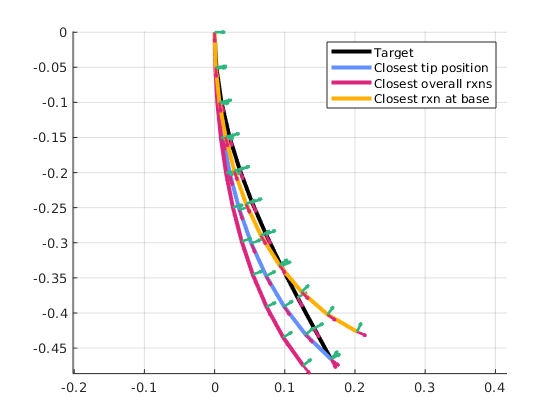

opts = optimoptions("fsolve", MaxFunctionEvaluations=4e5, MaxIterations=5e3, StepTolerance=1e-8, FunctionTolerance=1e-8, Algorithm="levenberg-marquardt", Display="off");
f = @(mat_in) check_equilibrium(mat_in, Q_tip, soln_p_min_residual, struct_design);
[soln_mimic_shape, res, ~, output, J_end] = fsolve(f, default_segment_twists, opts);
if norm(res) > 0.01, disp(res), end

f = @(mat_in) check_equilibrium(mat_in, Q_tip, soln_p_rxn_at_base, struct_design);
[soln_mimic_rxns, res, ~, output, J_end] = fsolve(f, default_segment_twists, opts);
if norm(res) > 0.01, disp(res), end

f = @(mat_in) check_equilibrium(mat_in, Q_tip, soln_p_closest_tip, struct_design);
[soln_closest_tip, res, ~, output, J_end] = fsolve(f, default_segment_twists, opts);
if norm(res) > 0.01, disp(res), end

ax = axes(figure());
hold on

red = [220 38 126] / 255;
blue = [100 143 255] / 255;
yellow = [255 176 0] / 255;
green = [45 182 125] / 255;

plot_poses(calc_poses(g_0, segment_twists), ax, "k", true, 0.1)
plot_poses(calc_poses(g_0, soln_closest_tip), ax, struct(color=blue), true, 0.1);
plot_poses(calc_poses(g_0, soln_mimic_shape), ax, struct(color=red), true, 0.1);
plot_poses(calc_poses(g_0, soln_mimic_rxns), ax, struct(color=yellow), true, 0.1);

grid on
legend("Target", "Closest tip position", "Closest overall rxns", "Closest rxn at base")
set(gcf, "Visible", true)

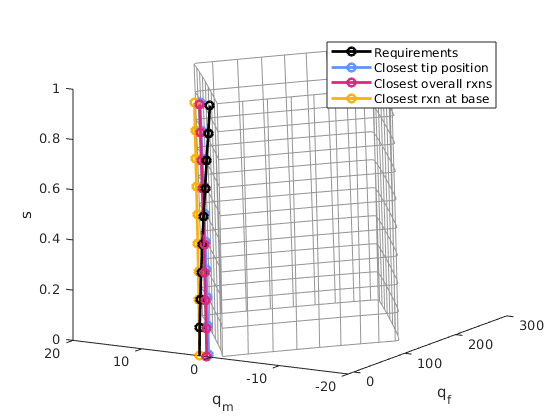

gray = [150 150 150] / 255;

figure()
hold on
plot3(a_target(1, :), a_target(3, :), s, 'k-o', "linewidth", 2)
plot3(soln_a_closest_tip(1, :), soln_a_closest_tip(3, :), s, '-o', "color", blue, "linewidth", 2)
plot3(soln_a_min_residual(1, :), soln_a_min_residual(3, :), s, '-o', "color", red, "linewidth", 2)
plot3(soln_a_rxn_at_base(1, :), soln_a_rxn_at_base(3, :), s, '-o', "color", yellow, "linewidth", 2)
plot3(paths_qf(:, 1:3:end)', paths_qm(:, 1:3:end)', s, "color", gray);
plot3(paths_qf', paths_qm', mat_s, "color", gray);

xlabel("q_f")
ylabel("q_m")
zlabel("s")
legend("Requirements", "Closest tip position", "Closest overall rxns", "Closest rxn at base")
view(-60, 15)
set(gcf, "visible", true)

% Let's compare this to the reaction prism of one of the different
% equilibrium shapes. For example, the one from minimizing tip distance:
mat_rxns_closest_tip = zeros([size(reaction_forces), length(t)]);
for i = 1 : size(ps, 2)
    mat_rxns_closest_tip(:, :, i) = calc_reaction_wrench(soln_closest_tip, ps(:, i), struct_design);
end

% For each element within the segment, track how the reactions moved as we
% traversed the pressure contour.
paths_qf_closest_tip = zeros(N_poses, length(t));
paths_qm_closest_tip = zeros(N_poses, length(t));
text_labels = cell(1, N_poses);
for i = 1 : N_poses
    paths_qf_closest_tip(i, :) = squeeze(mat_rxns_closest_tip(1, i, :));
    paths_qm_closest_tip(i, :) = squeeze(mat_rxns_closest_tip(3, i, :));
    text_labels{i} = sprintf("s=%.2f", s(i));
end

rxns_closest_tip = calc_reaction_wrench(soln_closest_tip, soln_p_closest_tip, struct_design);
q_closest_tip = -calc_external_wrench(soln_closest_tip, Q_tip, struct_design.g_0);

figure("Position", [0, 0, 1200, 400])
subplot(1, 2, 1)
hold on
plot3(q_closest_tip(1, :), q_closest_tip(3, :), s, 'k-o', "linewidth", 2)
plot3(rxns_closest_tip(1, :), rxns_closest_tip(3, :), s, '-o', "color", blue, "linewidth", 2)
plot3(paths_qf_closest_tip(:, 1:3:end)', paths_qm_closest_tip(:, 1:3:end)', s, "color", gray);
plot3(paths_qf_closest_tip', paths_qm_closest_tip', mat_s, "color", gray);
xlabel("q_f")
ylabel("q_m")
zlabel("s")
legend("Requirements", "Closest possible")
view(-60, 15)
set(gcf, "visible", true)

ax = subplot(1, 2, 2)

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


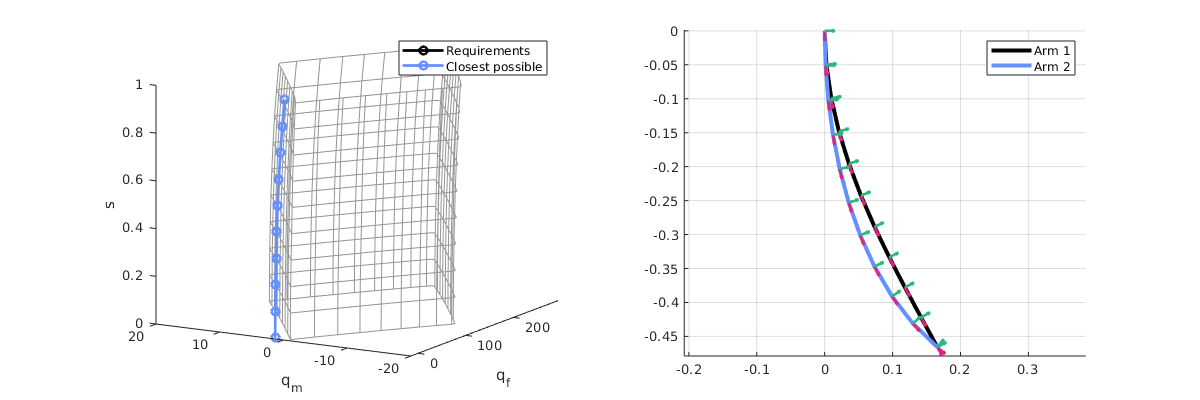

hold on

plot_poses(calc_poses(g_0, segment_twists), ax, "k", true, 0.1)
plot_poses(calc_poses(g_0, soln_closest_tip), ax, struct(color=blue), true, 0.1);

grid on
legend("Arm 1", "Arm 2")

set(gcf, "Visible", true)

function poses = f_calc_poses(g_0, f_segment_twists, N_poses)
    s = linspace(0, 1, N_poses);
    mat_segment_twists = f_segment_twists(s);
    poses = calc_poses(g_0, mat_segment_twists);
end

function ps = outline_pressure_space(max_ps, actuation_mode, N_edge)
    %%% Create a square path in pressure-space with N_edge points along each
    %%% edge using a corner definition: min_ps defines the bottom left
    %%% corner, and max_ps defines the top right corner. The path begins
    %%% and ends at the bottom left corner.
    %%%
    %%% Parameters:
    %%%  - max_ps: [60, 100, 100, 60] (kpa)
    %%%  - actuation_mode: [1 2 1 2]
    %%%  - N_edge: 50

    % Determine the phases of each trapezoid wave based on the actuation
    % modes. 
    % Currently mode-2 is defined starting a quarter period later than mode1
    phases = zeros(size(actuation_mode));
    for i = 1 : length(actuation_mode)
        mode_i = actuation_mode(i);
        
        if mode_i == 1
            phases(i) = 0;
        elseif mode_i == 2
            phases(i) = 1;
        end
    end
    
    t = linspace(0, 4, N_edge*4);
    ps = zeros(length(max_ps), length(t));
    for i = 1 : length(max_ps)
        ps(i, :) = max_ps(i) * trapezoid_wave(t - phases(i));
    end
end

function sig = trapezoid_wave(s)
    %%% Sample a trapzoid wave with period 1s at times s.
    %%% The trapezoid has amplitude 0.5 and is centered at 0.5
    %%% ie, it switches between 0 and 1.
    s = mod(s, 4);
    sig = zeros(size(s));
    for i = 1 : length(s)
        s_i = s(i);
        
        if s_i < 1
            sig(i) = 1 * (s_i);
        elseif (s_i >= 1) && (s_i < 2)
            sig(i) = 1;
        elseif (s_i >= 2) && (s_i < 3)
            sig(i) = -1 * (s_i - 2) + 1;
        else
            sig(i) = 0;
        end
    end
end

function cost = cost_first_reaction_diff(twists, pressure, struct_design, a_target)
    rxns = calc_reaction_wrench(twists, pressure, struct_design);
    cost = norm(rxns(:, 1) - a_target(:, 1));
end

function cost = cost_tip_pose_error(twists_0, pressure, Q_tip, struct_design, g_target)
    opts = optimoptions("fsolve", MaxFunctionEvaluations=4e5, MaxIterations=5e3, StepTolerance=1e-8, FunctionTolerance=1e-8, Algorithm="levenberg-marquardt", Display="off");
    f = @(mat_in) check_equilibrium(mat_in, Q_tip, pressure, struct_design);
    
    soln = fsolve(f, twists_0, opts);
    
    poses = calc_poses(struct_design.g_0, soln);
    delta_g_extrinsic = Pose2.vee(poses(:, :, end)) - Pose2.vee(g_target);
    K = diag([1 1 0]);
    cost = delta_g_extrinsic' * K * delta_g_extrinsic;
    %delta_g = inv(poses(:, :, end)) * g_target;
    %cost = norm(Twist2.vee(logm(delta_g)));
end